# Quantized Deep Neural Network on Jetson AGX Xavier Using GPU Coder

This example shows how to create and train a simple convolutional neural network for defect detection, how to quantize network and how to generate code to implement pre/post image processing algorithms and convolutional neural network into Jetson AGX Xavier.

This example demonstrates how to:

- Load and explore image data

- Define the network architecture and training options

- Train the network and classify validation images

- Quantize network to reduce memory footprint

- Walk through whole algorithm that consist of pre-processing, CNN and post-processing

- Generate CUDA C++ code(MEX) for whole algorithm

- Deploy algorithms to NVIDIA hardware

- Run the Executable on the Target

### Prerequisites - MathWorks Products and Support Packages

- MATLAB Coder™

- GPU Coder™

- Parallel Computing Toolbox™

- Deep Learning Toolbox™

- Image Processing Toolbox™

- Computer Vision Toolbox™

### Prerequisites - Development Host Requirements

- NVIDIA® GPU enabled for CUDA with compute capability 3.2 or higher (6.1 or higher is required for quantization)

- NVIDIA CUDA toolkit and driver

- C/C++ Compiler 

- CUDA Deep Neura Network library (cuDNN)

- Open Source Computer Vision Library v3.1.0 or higher for reading and displaying images/video

- (Optional) NVIDIA TensorRT

- The support package GPU Coder Interface for Deep Learning

- GPU Coder Support Package for NVIDIA GPUs

- The support package Deep Learning Toolbox Model Quantization Library. To install support packages, use the Add-On Explorer.

- Environment variables for the compilers and libraries. For information on the supported versions of the compilers and libraries, see [Third-party Products](https://jp.mathworks.com/help/gpucoder/gs/install-prerequisites.html). For setting up the environment variables, see [Setting Up the Prerequisite Products](https://jp.mathworks.com/help/gpucoder/gs/setting-up-the-toolchain.html).

### Prerequisites - Target Board Requirements

- NVIDIA Jetson AGX Xavier

- Ethernet crossover cable to connect the target board and host PC (if the target board cannot be connected to a local network)

- NVIDIA CUDA toolkit and driver

- CUDA Deep Neura Network library (cuDNN)

- Open Source Computer Vision Library v3.1.0 or higher for reading and displaying images/video

- Environment variables on the target for the compilers and libraries. For information on the supported versions of the compilers and libraries and their setup, see [installing and setting up prerequisites for NVIDIA boards](https://www.mathworks.com/help/supportpkg/nvidia/ug/install-and-setup-prerequisites.html).

clear; close all; imtool close all; clc;rng('default')

## 1. Load and explore image data

Load the sample data as an image datastore

categ = {'good', 'defective'};
imds = imageDatastore(fullfile(pwd, 'trainingImages', categ), 'IncludeSubfolders',1,'LabelSource', 'foldernames')

imds =   ImageDatastore のプロパティ:

                       Files: {
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame1.png';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame10.png';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame100.png'
                               ... and 779 more
                              }
                     Folders: {
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\defective'
                              }
                      Labels: [good; good; good ... and 779 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
  

imds.ReadFcn = @(filename) readFunctionTrain(filename);
% Prepare data for TensorRT int8 calibration.
% Loaded image we have now is all gray scale image. Copy and stack gray scale image
% three times to replicate the 3 channels of RGB. We can do the same thing by
% assigning ReadFcn to imageDatastore instead, but we can't use datastore for TensorRT calibration and 
% need to prepare RGB data stored in the specific folder. 
prepareData4Calibration(imds)
countEachLabel(imds)

ans = 2×2 table
      Label      Count
    _________    _____

    defective     509 
    good          273 


### Display some of the images of defect product(hexagon nut) in the datastore

These nuts has scratch or scoring on a surface

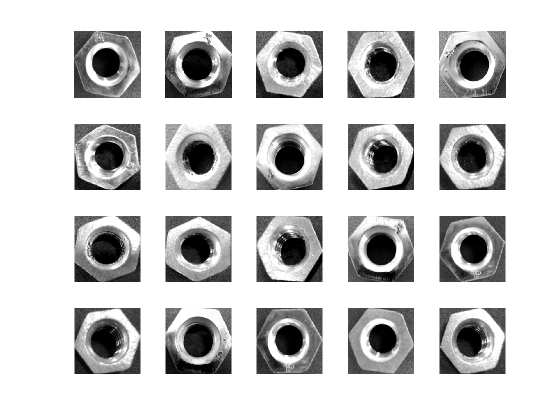

figure;
idx = find(imds.Labels == 'defective');
perm = randperm(size(idx,1),20);
for i = 1:20
    subplot(4,5,i);
    imshow(readimage(imds, idx(perm(i))));
end

### Specify Training and Validation Sets

Separate the sets into training and validation data. Pick 90% of images from each set for the training data and the remainder, 10%, for the validation data

[trainingSet, validationSet] = splitEachLabel(imds, 0.9, 'randomize');

## 2. Define the Network Architecture and Training Options

Load pretrained Squeezenet v1.1 as an base network. The pretrained network can classify images into 1000 object categories, such as keyboard, mouse, pencil, and many animals. To retrain SqueezeNet to classify new images, place new fully connected layer with the number of outputs equal to the number of classes in the new data set (2, in this example). 

net = squeezenet;
inputSize = net.Layers(1).InputSize;

lgraph = layerGraph(net);
% Remove layers configured for 1000 classes
lgraph = removeLayers(lgraph, {'prob','ClassificationLayer_predictions'});
% Define new layers for 2 classes classification
newLayers = [...
    fullyConnectedLayer(2,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','prob')
    classificationLayer('Name','classoutput')];
% % Add new layers to layer graph
lgraph = addLayers(lgraph,newLayers);
% % Connect layers in layer graph
lgraph = connectLayers(lgraph,'pool10','fc');

### Data Augmentation

Data augmentation is used during training to provide more examples to the network because it helps improve the accuracy of the network. Here, random X/Y reflection and random rotation in the range of 180 180] is used for data augmentation.

augmenter = imageDataAugmenter('RandXReflection',true,'RandYReflection',true,...
    'RandRotation', [-180 180]);
datasource = augmentedImageSource(inputSize(1:2),trainingSet,'DataAugmentation',augmenter);

### Specify Training Options

Set `InitialLearnRate` to a small value to slow down learning in the transferred layers. In the previous step, you increased the learning rate factors for the fullyConnected layer to speed up learning in the new final layers.Set the maximum number of epochs for training to 15, and use a mini-batch with 32 observations at each iteration. Turn on the training progress plot.

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.7, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize',32,...
    'ValidationData',validationSet, ...
    'ValidationFrequency',30, ...
    'ValidationPatience',Inf, ...
    'Plots','training-progress');

## 3. Train Network Using Training Data

Train the network using the training data. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, `trainNetwork` uses a CPU.

Note: The training was verified on an NVIDIA™ GeForce GTX 1070. Training this network takes about ~1 minite.

単一の GPU で学習中。
入力データの正規化を初期化しています。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　３１．２５％　｜　６５．３８％　｜　　　１０．６９５９　｜　３．９１０８　｜　１．００００ｅ－０４　｜


｜　　　　　　２　｜　　　３０　｜　　　　　００：００：１２　｜　　　　　６８．７５％　｜　６６．６７％　｜　　　　０．６１９６　｜　０．５９９４　｜　１．００００ｅ－０４　｜


｜　　　　　　３　｜　　　５０　｜　　　　　００：００：１９　｜　　　　　６５．６３％　｜　　　　　　　　｜　　　　０．５６６４　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　　３　｜　　　６０　｜　　　　　００：００：２２　｜　　　　　５６．２５％　｜　６５．３８％　｜　　　　０．５７７９　｜　０．５３７９　｜　１．００００ｅ－０４　｜


｜　　　　　　５　｜　　　９０　｜　　　　　００：００：３２　｜　　　　　７１．８８％　｜　６９．２３％　｜　　　　０．４３０３　｜　０．４８２１　｜　１．００００ｅ－０４　｜


｜　　　　　　５　｜　　１００　｜　　　　　００：００：３５　｜　　　　　８１．２５％　｜　　　　　　　　｜　　　　０．３８４７　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　　６　｜　　１２０　｜　　　　　００：００：４２　｜　　　　　７５．００％　｜　７６．９２％　｜　　　　０．３９１７　｜　０．３５０６　｜　１．００００ｅ－０４　｜


｜　　　　　　７　｜　　１５０　｜　　　　　００：００：５２　｜　　　　　９３．７５％　｜　９４．８７％　｜　　　　０．１９９７　｜　０．１５１０　｜　１．００００ｅ－０４　｜


｜　　　　　　９　｜　　１８０　｜　　　　　００：０１：０２　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０１６２　｜　０．０４２７　｜　１．００００ｅ－０４　｜


｜　　　　　１０　｜　　２００　｜　　　　　００：０１：０９　｜　　　　　９６．８８％　｜　　　　　　　　｜　　　　０．０４７７　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　１０　｜　　２１０　｜　　　　　００：０１：１２　｜　　　　１００．００％　｜　９７．４４％　｜　　　　０．０６３４　｜　０．０４５６　｜　１．００００ｅ－０４　｜


｜　　　　　１１　｜　　２４０　｜　　　　　００：０１：２２　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０３０１　｜　０．０４１０　｜　７．００００ｅ－０５　｜


｜　　　　　１２　｜　　２５０　｜　　　　　００：０１：２５　｜　　　　１００．００％　｜　　　　　　　　｜　　　　０．０３４３　｜　　　　　　　　｜　７．００００ｅ－０５　｜


｜　　　　　１３　｜　　２７０　｜　　　　　００：０１：３１　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０３５６　｜　０．０２７６　｜　７．００００ｅ－０５　｜


｜　　　　　１４　｜　　３００　｜　　　　　００：０１：４０　｜　　　　　９６．８８％　｜　９８．７２％　｜　　　　０．０３８３　｜　０．０２６４　｜　７．００００ｅ－０５　｜


｜　　　　　１５　｜　　３３０　｜　　　　　００：０１：４９　｜　　　　　９６．８８％　｜　９８．７２％　｜　　　　０．０４０８　｜　０．０５６７　｜　７．００００ｅ－０５　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


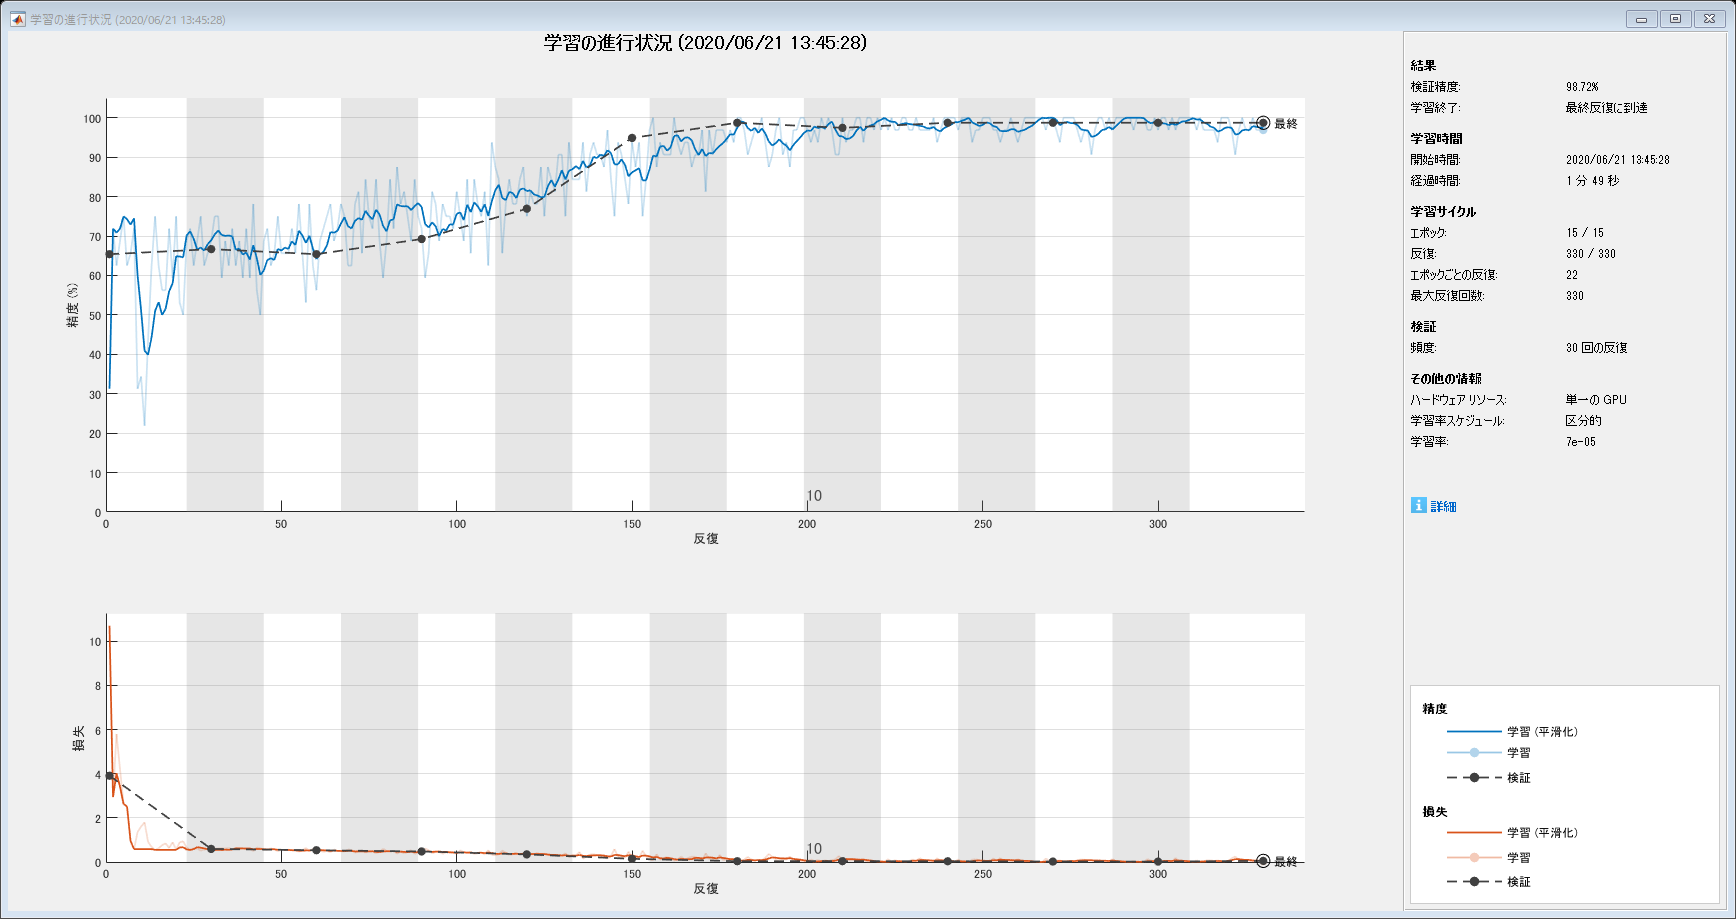

trainnet = true;
if trainnet
    convnet = trainNetwork(datasource,lgraph,options);
    save('mySqueezeNet.mat','convnet')
else
    % Load pre-trained network
    load('mySqueezeNet.mat')
end

### Classify Validation Images Using Trained Network

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

predictedLabels = classify(convnet, validationSet);
valLabels = validationSet.Labels;

accuracy = sum(predictedLabels == valLabels)/numel(valLabels)

accuracy = 0.9872

Read sample validation image and classify it

idx = 65;
[img, info] = readimage(validationSet, idx);
info.Label

ans = categorical
     defective 


[out, score] = classify(convnet, img)

out = categorical
     defective 


score = 1×2 の single 行ベクトル
    1.0000    0.0000


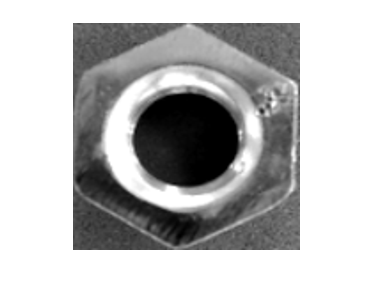

figure, imshow(img)

## 4. Quantize Network to Reduce Memory Footprint

Quantization of a neural network requires a GPU, the GPU Coder Interface for Deep Learning Libraries support package, and the Deep Learning Toolbox Model Quantization Library support package. Using a GPU requires a CUDA enabled NVIDIA GPU with compute capability 6.1 or higher. If GPU with compute capability 6.1 or higher is not available on your machine, skip this step and go to next step(5. Walk through whole algorithm that consist of pre-processing, CNN and post-processing). For more details see [Quantization of Deep Neural Networks](https://jp.mathworks.com/help/gpucoder/ug/quantization-of-deep-neural-networks.html)(GPU Coder).

Check if host machine has available GPU for quantization process.

doCalib = false;
try 
    gpuInfo = gpuDevice;
    if gpuInfo.ComputeCapability > 6.0
        doCalib = true;
        disp('Network calibration can be run on this machine.')
    else
        disp(['GPU is available on this machine, but compute capability is ', gpuInfo.ComputeCapability, '.'])
    end
catch
    disp('Calibration process reuires CUDA Enabled GPU with compute capability 6.1 or higher.')
end

Network calibration can be run on this machine.


if doCalib

Prepare calibration data and quantizer object for quantization

datasource_val = augmentedImageSource([227 227],validationSet,'DataAugmentation',augmenter);
% Create quantizer object
quantObj = dlquantizer(convnet);
% Specify the metric function in a dlquantizationOptions object
quantOpts = dlquantizationOptions('MetricFcn', ...
    {@(x)computeModelAccuracy(x, convnet, datasource_val)});

Start calibration to simulate the network with sample inputs

calResults = calibrate(quantObj, datasource)

calResults = 98×5 table
                   Optimized Layer Name                      Network Layer Name        Learnables / Activations    MinValue     MaxValue
    __________________________________________________    _________________________    ________________________    _________    ________

    {'conv1_relu_conv1_Weights'                      }    {'relu_conv1'           }           "Weights"             -0.91934     0.88411
    {'conv1_relu_conv1_Bias'                         }    {'relu_conv1'           }           "Bias"               -0.080732     0.26546
    {'fire2-squeeze1x1_fire2-relu_squeeze1x1_Weights'}    {'fire2-relu_squeeze1x1'}           "Weights"              -1.3791      1.2459
    {'fire2-squeeze1x1_fire2-relu_squeeze1x1_Bias'   }    {'fire2-relu_squeeze1x1'}           "Bias"                 -0.1171     0.24211
    {'fire2-expand1x1_fire2-relu_expand1x1_Weights'  }    {'fire2-relu_expand1x1' }           "Weights"              -0.7391     0.91082
    {'fire2-expa

### Quantize and simulate the network

valResults = validate(quantObj, datasource_val, quantOpts);
valResults.MetricResults.Result

ans = 2×3 table
    NetworkImplementation    MetricOutput    LearnableParameterMemory(bytes)
    _____________________    ____________    _______________________________

     {'Floating-Point'}        0.97436                   4.95e+06           
     {'Quantized'     }        0.98718                 1.2554e+06           


Save Quantizer Object

save('dlquantObj.mat', 'quantObj');

In this example, the memory required for the network was reduced approximately 75% through quantization. The accuracy of the network is not affected.

end

## 5. Walk through whole algorithm that consist of pre-processing, CNN and post-processing

Read new image captured by webCam. The images used to train network were pre-processed image to fit it in input image size of network. Original image captured by webCam is like this;

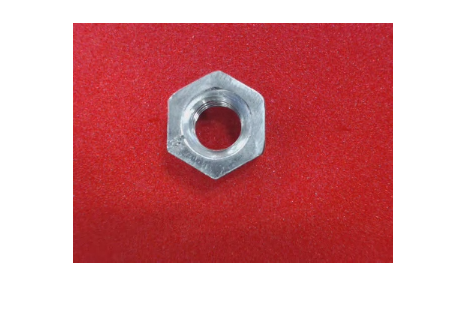

img = imread('images/defective.png');
figure, imshow(img)

So, we need to extract where the nuts are as an ROI before passing image to the neural network.

### Pre-processing for captured image from webCam

myNDNet_Preprocess is to extract ROI by using traditional image processing. Since generated C code from this m code will be integrated into main.cpp that uses OpenCV format, some format conversion need to be considerd.

wi = uint32(320);
he = uint32(240);
ch = uint32(3);

imgOcv = mat2ocv(img);
[Iori, nuts, num, bbox] = myNDNet_Preprocess(imgOcv);

### Display pre-processed image(extracted nuts)

Now, we have cropped images for each hexagon nut. Display these images here.

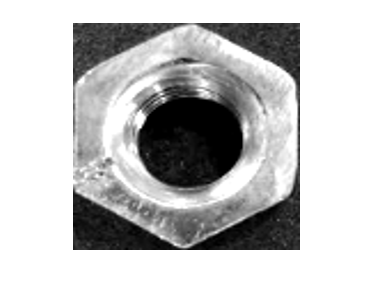

figure,
for i = 1:num
    subplot(1,num,i)
    imshow(nuts(:,:,i))
end

### Classify detected nuts by using pretrained network

Comfirm if pretrained network works well for clopped images for each hexagon nut, and perform class activation mapping(CAM). Class activation mapping (CAM) is helpful to investigate and explain the predictions of a deep convolutional neural network for image classification.

Weights = convnet.Layers(67).Weights;
scores = zeros(2,4);
HeatMap = zeros(227,227,3,4);
for i = 1:num
    indata = repmat(nuts(:,:,i), [1 1 3]);
    scores(:,i) = convnet.predict(indata);
    act = convnet.activations(indata,'relu_conv10','OutputAs','channels');
    HeatMap(:,:,:,i) = CAMheatmap_squeezenet(indata,act,scores(:,i),Weights);
end
scores

scores =     1.0000         0         0         0
    0.0000         0         0         0


### Insert the labels in an image as an post-processing

out = myNDNet_Postprocess(Iori, num, bbox, scores, wi, he, ch, HeatMap);

### Display post-processed image

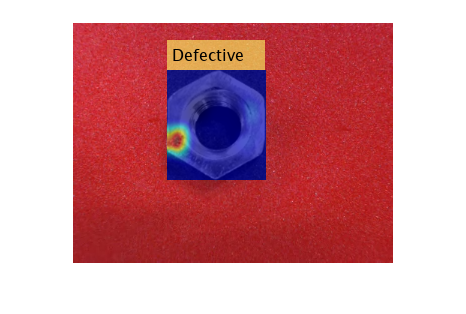

sz = [he wi ch];
out = ocv2mat(out,sz);

figure, imshow(out)

The hexagon nut is classified as "defective" and class activation map shows which regions of the input image contribute the most to the predicted class "defective".  We can see that whole algorithm works well on this result.

### Merge pre/post processing and prediction into a function for code generation

targetFunction.m is the function that includes all algorithms for defect detection.

out2 = targetFunction(imgOcv,Weights,true);

out2 = ocv2mat(out2,sz);
figure, imshow(out2)

## 6. Generate CUDA C++ code(MEX) for 'targetFunction'

Create a GPU configuration object for a MEX target and set the target language to C++. Use the coder.DeepLearningConfig function to create a cuDNNTensorRT deep learning configuration object and assign it to the DeepLearningConfig property of the GPU code configuration object. For an overview and tutorials for code generation using GPU Coder, visit the [GPU Coder product page](https://www.mathworks.com/products/gpu-coder).

% Select Library for Deep Neural Network
useTensorRT = 0; % 0:cuDNN(int8), 1:TensorRT(fp32), 2:TensorRT(int8) 

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';

% Check compute capability of GPU
gpuInfo = gpuDevice;
cc = gpuInfo.ComputeCapability;

% Create deep learning code generation configuration object
switch useTensorRT
    case 0
        cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
        if doCalib
            cfg.DeepLearningConfig.CalibrationResultFile = fullfile(pwd,'dlquantObj.mat');
            cfg.DeepLearningConfig.DataType = 'int8';
        end
    case 1
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        cfg.GpuConfig.ComputeCapability = cc;
        cfg.DeepLearningConfig.DataType = 'fp32';        
    otherwise
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        % INT8 precision requires a CUDA GPU with minimum compute capability of
        % 6.1, except 6.2
        cfg.GpuConfig.ComputeCapability = cc;
        cfg.DeepLearningConfig.DataType = 'int8';
        cfg.DeepLearningConfig.DataPath = 'calibImages';
end

codegen -config cfg targetFunction -args {ones(240, 320, 3,'uint8'), coder.Constant(Weights), coder.Constant(true)} -report

コードの生成が成功しました:レポートの表示


### Run Generated MEX on the host machine

Confirm if generated mex runs correctly without any errors.

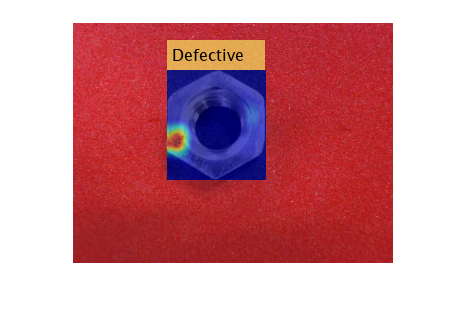

out = targetFunction_mex(imgOcv,Weights,true);
out = ocv2mat(out,sz);
figure, imshow(out)

## 7. Deploy algorithms to NVIDIA hardware

Now, we have pretrained network and pre/post image processing as an targetFunction.m that is verified compatibility with GPU Coder. GPU Coder enable you to generate CUDA C++ code from MATLAB algorithms, and GPU Coder support package for NVIDIA GPUs enable you to automates the deployment this algorithm on embedded NVIDIA GPUs by building and deploying the generated CUDA code on the target GPU hardware board. For more details on using this support package, visit [Getting Started with the GPU Coder Support Package for NVIDIA GPUs](https://www.mathworks.com/help/gpucoder/examples/getting-started-with-the-gpu-coder-support-package-for-nvidia-gpus.html)

### Connect to the NVIDIA Hardware

The GPU Coder Support Package for NVIDIA GPUs uses an SSH connection over TCP/IP to execute commands while building and running the generated CUDA code on the NVIDIA Jetson/DRIVE platform. You must connect the target platform to the same network as the host computer or use an Ethernet crossover cable to connyaect the board directly to the host computer.

% You must know the host name or IP address, username, and password of the target board
hwobj = jetson('192.168.0.102', 'nvidia', 'nvidia')

Checking for CUDA availability on the Target...
Checking for 'nvcc' in the target system path...
Checking for cuDNN library availability on the Target...
Checking for TensorRT library availability on the Target...
Checking for prerequisite libraries is complete.
Gathering hardware details...
Checking for third-party library availability on the Target...
Gathering hardware details is complete.
 Board name         : NVIDIA Jetson AGX Xavier
 CUDA Version       : 10.0
 cuDNN Version      : 7.3
 TensorRT Version   : 5.0
 GStreamer Version  : 1.14.1
 V4L2 Version       : 1.14.2-1
 SDL Version        : 1.2
 Available Webcams  :  
 Available GPUs     : Xavier


hwobj =   jetson のプロパティ:

       DeviceAddress: '192.168.0.102'
                Port: 22
           BoardName: 'NVIDIA Jetson AGX Xavier'
         CUDAVersion: '10.0'
        cuDNNVersion: '7.3'
     TensorRTVersion: '5.0'
          SDLVersion: '1.2'
         V4L2Version: '1.14.2-1'
    GStreamerVersion: '1.14.1'
             GPUInfo: [1×1 struct]
          WebcamList: []


### Verify the GPU Environment

Use the coder.checkGpuInstall function and verify that the compilers and libraries needed for running this example are set up correctly

envCfg = coder.gpuEnvConfig('jetson');
envCfg.BasicCodeexec = 1;
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodeexec = 1;
envCfg.HardwareObject = hwobj;
coder.checkGpuInstall(envCfg)

互換性のある GPU               : パス 
CUDA 環境                  : パス 
	ランタイム     : パス 
	cuFFT     : パス 
	cuSOLVER  : パス 
	cuBLAS    : パス 
cuDNN 環境                 : パス (警告: 深層学習コード生成は、cuDNN v7.5 を使用してテストされました。指定された cuDNN ライブラリの v7.3 に完全な互換性がない可能性があります。)
基本的なコードの生成               : パス 
基本的なコードの実行               : パス 
深層学習 (cuDNN) コードの生成      : パス 
深層学習 (cuDNN) コードの実行      : パス 


ans = フィールドをもつ struct :
                 gpu: 1
                cuda: 1
               cudnn: 1
            tensorrt: 0
        basiccodegen: 1
       basiccodeexec: 1
         deepcodegen: 1
        deepcodeexec: 1
    tensorrtdatatype: 0
           profiling: 0


### Generate CUDA Code for the Target Using GPU Coder

To generate a CUDA executable that can deployed on to a NVIDIA target, create a GPU code configuration object for generating an executable.

cfg = coder.gpuConfig('exe');
cfg.TargetLang = 'C++';
% Use the coder.hardware function to create a configuration object for the Jetson platform
% and assign it to the Hardware property of the code configuration object cfg.
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/remoteBuildDir';
cfg.CustomSource  = fullfile('main_nutsCam.cpp');

% Select Library for Deep Neural Network
useTensorRT = 0; % 0:cuDNN(int8), 1:TensorRT(fp32), 2:TensorRT(int8) 
% Create deep learning code generation configuration object
switch useTensorRT
    case 0
        cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
        if doCalib % Calibration 
            cfg.DeepLearningConfig.CalibrationResultFile = 'dlquantObj.mat';
            cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
            cfg.DeepLearningConfig.DataType = 'int8';
        end        
    case 1
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
        cfg.DeepLearningConfig.DataType = 'fp32';        
    otherwise
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        % INT8 precision requires a CUDA GPU with minimum compute capability of
        % 6.1, except 6.2
        cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
        cfg.DeepLearningConfig.DataType = 'int8';
        cfg.DeepLearningConfig.DataPath = 'calibImages';
end

To generate CUDA code, use the codegen function and pass the GPU code configuration object. After the code generation takes place on the host, the generated files are copied over and built on the target.

codegen -config cfg targetFunction -args {ones(240,320,3,'uint8'),coder.Constant(Weights),coder.Constant(false)} -report

コードの生成が成功しました:レポートの表示


## 8. Run the Executable on the Target

Copy the input test image to the target directory where remote build process was performed in. putFile can be used to transfer file from host computer to taret hardware.

putFile(hwobj, 'images/defective.png', hwobj.workspaceDir);

### Launch the executable on the target hardware

Use the runExecutable() method of the hardware object to launch the executable 

exe = [hwobj.workspaceDir '/targetFunction.elf'];
useWebcam = false;
if ~useWebcam
    pid = hwobj.runExecutable(exe, ' 3 defective.png'); % Provide the input image;
else
    % Or if you have webCam connected to Jetson, you can use captured
    % image from webCam instead.
    pid = hwobj.runExecutable(exe, ' 1 0'); % "0" is deviceID for webCam
end

### Launching the executable on the target...
Executable launched successfully with process ID 13674.
Displaying the simple runtime log for the executable...

Note: For the complete log, run the following command in the MATLAB command window:
system(hwobj,'cat /home/nvidia/remoteBuildDir/MATLAB_ws/R2020a/C/Users/keitaro/OneDrive_-_MathWorks/Demos/DeepLearning/H7_CAM/FEX/targetFunction.log')


### Transfer file from target hardware to host computer

The defect detection result against input image is saved as an output.png file on the target hardware. Use getFile to transfer file from target hardware to the host machine. If you use webCam instead of providing image file, the image output is displayed in a window on the monitor connected to the target board.

if ~useWebcam
    imgData = [hwobj.workspaceDir '/output.png'];
    getFile(hwobj, imgData)
end

### Display output image transfered from target hardware

if ~useWebcam
    img = imread('output.png');
    figure, imshow(img)
else
    % You can kill the running executable on the target from the MATLAB environment on the host 
    % by using the killProcess() method of the hardware object.
    killProcess(hwobj, pid);
end

## Supporting Function

function I = readFunctionTrain(filename)
% Resize images to the size required by the network.
I = imread(filename);

if ismatrix(I)
    I = cat(3,I,I,I);
end
I = imresize(I, [227 227]);
end

*Copyright 2020 The MathWorks, Inc.*